# Controlling the Position

Now that the Attitude Controller gains are tuned, we can control the attitude of our multirotor to move it around. For this purpose, we have a Position Controller module which takes the desired position and yaw and does two things:

- Calculates the desired attitude (roll, pitch and yaw) for the Attitude Controller.

- Calculates some acceleration command that will move the multirotor to the desired position.

In this task, first, you will calculate the desired attitude from a given acceleration and desired yaw and then you will implement a PID loop for the Position Controller. Finally, you will tune the gains for your newly written controller.

*Note that you need to run *`task1.mlx`* first before being able to work on this task. Just run it first with your final PID gains if you have not done so yet:*

%task1();

## Calculating the Attitude

Let's start with calculating the attitude for our Attitude Controller module to control. Assuming that we have the desired acceleration (in global frame) and the desired yaw (in degrees), we know that the multirotor should tilt in a way that the total generated thrust aligns with its Z axis. So, first we need to obtain the thrust direction from the acceleration command by subtracting the gravity from it:


$$\vec{T} = \vec{a}_{cmd} - \vec{g}$$


We are using FRD (Forward-Right-Down) frame for the robot. Therefore, the Z axis can be simply extracted from the thrust as:


$$\hat{z} = -\frac{\vec{T}}{\|\vec{T}\|$$


To get the X axis, we can find the right side direction on the horizontal plane and find the vector normal to the right side and the Z axis:


$$\hat{x} = \frac{ 
\left[\matrix{ -\sin\psi_{des} \cr \cos \psi_{des} \cr 0} \right]
\times \hat{z}}{\left\| 
\left[\matrix{ -\sin\psi_{des} \cr \cos \psi_{des} \cr 0} \right]
\times \hat{z}\right\|}$$


Now, Y axis can be calculated from the Z and X axes:


$$\hat{y} = \hat{z} \times \hat{x}$$


We already know the yaw and only need the roll and pitch. Try to find the roll and pitch from the axes. You can draw the axes on a piece of paper and use trigonometry to get the roll and pitch. Or you can use matlab functions or search on the internet.

### Task #2.1: Implement Acceleration Calculation

Let's code it all. **Open "**`task2_1_calc_attitude.m"`** file and complete the code.**

Let's test if the code works by testing a few inputs and compare with the expected outputs: 

% Command                                         % Expected approximate result
a1 = task2_1_calc_attitude([0; 0; 0], 0)'         % [ 0      0       0  ]

a1 =      0     0     0


a2 = task2_1_calc_attitude([0; 0; -5], 30)'       % [ 0      0       30 ]

a2 =      0     0    30


a3 = task2_1_calc_attitude([5; 0; 0], 0)'         % [ 0      -27.0   0  ]

a3 =          0  -27.0151         0


a4 = task2_1_calc_attitude([0; 5; 0], 0)'         % [ 27.0   0       0  ]

a4 =    27.0151         0         0


a5 = task2_1_calc_attitude([5; 0; 0], 30)'        % [ -13.1  -23.8   30 ]

a5 =   -13.1272  -23.8239   30.0000


a6 = task2_1_calc_attitude([0; 5; 0], 30)'        % [ 23.2   -14.3   30 ]

a6 =    23.1644  -14.3017   30.0000


a7 = task2_1_calc_attitude([5; 0; -10], 30)'      % [ -7.0   -12.3   30 ]

a7 =    -7.0295  -12.3320   30.0000


a8 = task2_1_calc_attitude([5; 10; 0], 30)'       % [ 24.5   -43.6   30 ]

a8 =    24.4705  -43.5736   30.0000


a9 = task2_1_calc_attitude([8; 5; -10], 30)'      % [ 0.86   -25.4   30 ]

a9 =     0.8622  -25.4550   30.0000


If everything looks good, we are ready to implement the Position PID controller!

## Calculating the Acceleration

Now is the time to complete the Position Controller. As mentioned, the output acceleration is calculated using PID gains on the position and velocity errors:


$$\vec{a}_{cmd} = P \cdot e(t) + I \cdot \int_0^t e(t')dt' + D \cdot \dot{e}(t)$$


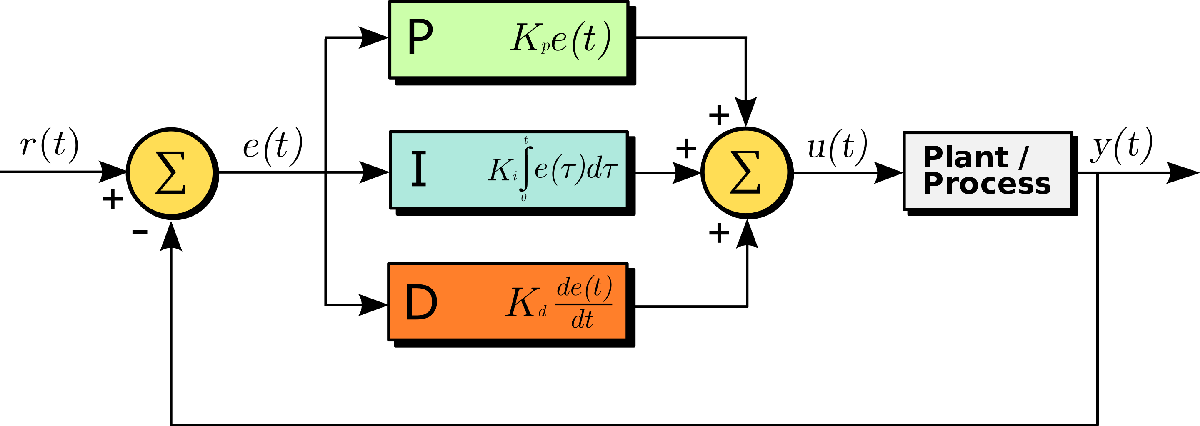

In our case, we can calculate the error term `e(t)` as the difference between desired position and the current position. For the derivative term, we can assume that our desired velocity is zero and calculate the velocity error based on that. For the integral term you need to keep the track of the position error integral and update it appropriately similar to this code:

### Task #2.2: Implement Acceleration Calculation

Let's implement a PID controller. **Open "**`task2_2_calc_acceleration.m"`** file and complete the code.**

After finishing the implementation, your position controller, and in fact, your whole multirotor is complete!!!

To test the implemented code let's increase our simulation time and set the initial conditions for the multirotor (a reminder that the inputs are (`pos, vel, rpy, omega)`):

sim.TotalTime = 20;
initial_position = [20; 10; 30];
initial_yaw = 0;
sim.Multirotor.SetInitialState(initial_position, zeros(3, 1), [0; 0; initial_yaw], zeros(3, 1));

*Note that in order to see a decent response to your Position Controller, you need a well-tuned Attitude Controller. Go back to task #1 and tune the PID gains as best as you can if you haven't done so yet, otherwise you will not be able to see a reasonable response.*

Let's see the response for a position command now. We can start with a conservative set of gains:

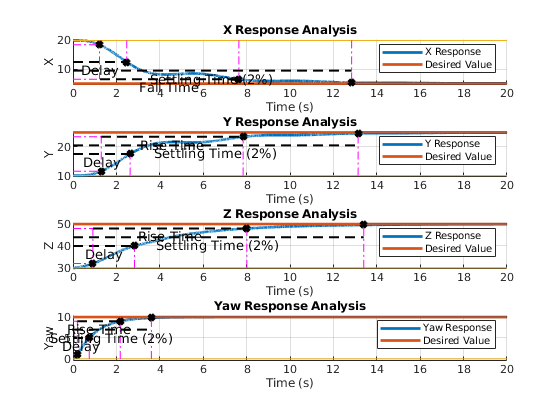

Analysis for response of X going from 20.00 to 5.00:
    Total Simulation Time: 20.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Overdamped
    Fall Time (10%-90%)  : 6.420 (s)
    Delay Time (0%-50%)  : 2.478 (s)
    Settling Time (2%)   : 12.842 (s)

Analysis for response of Y going from 10.00 to 25.00:
    Total Simulation Time: 20.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Overdamped
    Rise Time (10%-90%)  : 6.538 (s)
    Delay Time (0%-50%)  : 2.635 (s)
    Settling Time (2%)   : 13.140 (s)

Analysis for response of Z going from 30.00 to 50.00:
    Total Simulation Time: 20.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Overdamped
    Rise Time (10%-90%)  : 7.098 (s)
    Delay Time (0%-50%)  : 2.833 (s)
    Settling Time (2%)   : 13.396 (s)

Analysis for response of Yaw going from 0.00 to 10.00:
    Total Simulation Time: 20.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Over

sim.Controller.PositionController.SetPID(0.5, 0, 2);
desired_position = [5; 25; 50];
desired_yaw = 10;
sim.SimulatePositionResponse(desired_position, desired_yaw, true);

If you were able to track the desired signals you have done it right! Don't worry if the performance is not perfect, we are going to tune it next!

## Task #2.3: Tune it!

Tune the PID gains for the position controller above to get the best results that you can. In other words, try to minimize the unwanted effects such as overshoot and the different response times without causing motor saturation. I would recommend starting with only one of the signals (e.g., X), tuning it, then tuning the others separately and at the end test all of them together.

As before, the higher gain means the higher probability of motor saturations, but the lower gain generally means lower performance. Find the tradeoff. Start with only `P` gain (keep your `D` at 1 for now) and try to find a good response. Then increase the `D` gain until you are happy. Now go back to increasing `P` again and repeat the process interatively tuning `P` and `D` gains until you cannot make it better. You can skip tuning the `I` gain for now, but if you are interested you can experiment with that either. In other words, after finding your perfect `P` and `D` gains, slightly increase `I` until you see weird behavior or until you cannot make it better. Then go back and find the best `P` and `D` gains again with the new `I` and repeat the whole process. 

In addition to the response plots, you can also see other plots. Just use a recognizable name and the system will find out what signal you want. For example you may be interested in the attitude and velocity as well as motor saturations (you can check the `GetField` function in the `state_collection` class to see what strings to use for other signals, if interested):

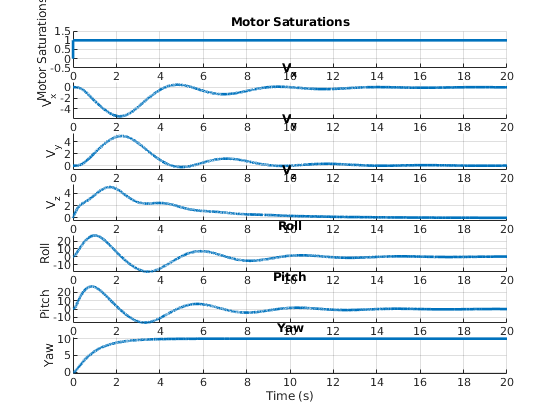

graphics.PlotSignalsByName(sim, 1, {'saturations', 'velocity', 'rpy'}, true);

Good luck!

## Copyright

Copyright (c) 2020 Carnegie Mellon University

This tool has been developed for educational purposes only as a control tutorial in *Air Lab Summer School 2020 *([https://theairlab.org](https://theairlab.org)). 

## Author

Azarakhsh Keipour (keipour [at] cmu.edu)

Please contact us for any questions or issues.